# **Servo Motor System Identification Activity Sheet**

**Student Name**: Alex Ong

**Student Number: 12435562**

### **Preparations for the task:**

In preparation for these tasks, download the 4 functions (MATLAB content-obscured executable files) 

- `GenerateRandomData.p, `

- `GenerateUnknownData.p, `

- `GenerateSEASpeedData.p` and 

- `EGB345_DataNameChecker_SysId.p` 

from CANVAS and ensure they are in the appropriate MATLAB path. In some browsers, you might need to right-click your mouse and select the “Save Link as” option.  Place them in the same directory as this .mlx file.  

The next code helps prepare your MATLAB work space (you don't need to edit, unless error occurs)

%The next 3 lines change MATLAB's current working folder to this .mlx script's current location.
filePath = matlab.desktop.editor.getActiveFilename;
filePath = fileparts(filePath);
cd(filePath)
%If causes a MATLAB error on your computer, remove these 3 code lines and manually change folder.

clear all
close all

# Overview

This activity involves modelling a servo motor system, which includes a motor, an arm, and internal electronics. The goal is to estimate the parameters of the transfer function that describes the system's behaviour using experimental step response data. In last task of this activity we investigate a Series Elastic Actuator (see also Practical 1).

# Modelling the Servo motor

This task is based on a servo motor mechanism commonly used in remote control aircraft. Simply speaking, the servo system has a motor, an arm, and a set of internal electronics. The motor is used to induce rotary (or linear) motion of the arm. There is a sensor attached which measures shaft angular velocity.

**Transfer function modelling:**

The simplified transfer function, input voltage to angle, can be approximated by:

                                                        
$$G(s)=\frac{\Theta(s)}{V_m(s)}=\frac{K_m}{s(s+\alpha)}$$
                

where $V_m$ is input signal and $\Theta$ is output shaft position. The transfer function is characterised by two parameters,$K_m$ and $\alpha.$These $K_m$ and $\alpha$ parameters absorb the specific values of the internal physical constants such as motor constants, the inertia of the load and the gear ratio that we saw in lecture slides and tutorial problems. IN a real setting, these $k_m$ and $\alpha$ parameters are not initially known.

**Experiment-based modelling with quantitative and qualitative assessment**

In this system identification task, we will use an **experiment-based modelling** approach in which we estimate the unknown  $K_m$ and $\alpha$ parameters of the transfer function from experimental capture step response data. An example of this step response datais the step time response to a *2V step response* shown in Figure 1 below.

In this system identification task, you will aim to have a good estimate the$k_m$ and $\alpha$parameters so that the **step response of the estimated **  best** matches** the step response data. A well-estimated servo motor model will mean that its step response has a good match with step response data.

In evaluating your performance at this system identification task, you will make both **quantitative** and** qualitative** **assessments**of the match of your estimated model to the step response data. In this context, the word `quantitative’ will refer to quantities (as in numbers) whilst the word `qualitative’ will refer to qualities (as in features or appearance).

# Assessed Questions

Complete the following 4 tasks. The provided .p functions will generate data unique to you.

## Task 1 (Data Plot):

#### Task 1.1: [Generate data] 

Create your randomly assigned data using the following MATLAB command:

***ANSWER (edit below code block)***

%Edit with your student number
yourstudentnumber=12435562;
[km, alpha] = GenerateRandomData('EGB345RandomData.csv',yourstudentnumber)

km = 9.7633

alpha = 4.5932

where `yourstudentnumber `is replaced by your student number.

This function will generate a CSV file (‘EGB345RandomData.csv’) that contains the following information:

- A time vector.

- Channel 1 is reading the 2V step response of motor speed. The angle have been measured by a potentiometer (has units of Volts).

Your true values of $K_m$ and $\alpha$ will also be stored in the variables ‘km’ and ‘alpha’, respectively. Please write these values down for your assessment submission.  Here “2V” means 2 Volt, and we highlight this is not a unit step input, which will impact your MATLAB code in later Tasks.

**Note: The GenerateRandomData ****function**** will generate different parameter values and noise values based on your student number.**

#### Task 1.2: [Read data]

Read the CSV file into your MATLAB workspace. The columns are labelled with text within the CSV file. This is to match the expected configuration as if you were taking these values from a real oscilloscope. 

***ANSWER (edit below code block)***

%edit here

servo_data = csvread('EGB345RandomData.csv',2,0);


#### **Task 1.3: [Plot data] **

Extract the original step response data (Channel 1) which you should name `'yn_random'`.   Plot Channel 1 versus the time vector. The plot of step response data will look qualitatively similar to the following when plotted. 

***ANSWER (edit below code block)***

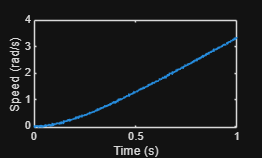

%edit here
second = servo_data(:,1);

yn_random = servo_data(:,2);

figure(122)

plot(second,yn_random)

xlabel('Time (s)')

ylabel('Speed (rad/s)')

## Task 2 (Build and test your estimator):

Your task is to design and implement a technique to estimate the values of $K_m$ and $\alpha$ that were used to generate the 2V step response data `yn_random `(from the data `yn_random `itself). Specifically, you are seeking quantitatively accurate estimated parameters so that the estimated step response is qualitatively similar to the data.

Here, the words ‘**quantitatively accurate**’ mean the estimated parameter values are quantitative (or numerically) close to the true parameter values (parameter value error can be expressed either as an absolute amount or as a percentage). Here, the words ’**qualitatively similar**’ mean that when plotted the estimated response has similar features to the data (the data `'yn_random' `in this task).

You are interested in both the quantitative and qualitatively properties of your estimate.

#### Task 2.1: [Compose Estimator] 

Write MATLAB code to estimate $K_m$ and $\alpha$ from data `yn_random. `Record your estimate. Provide an explanation of your estimation approach which addresses the following questions: What is your approach doing? Why is your approach useful? When might your approach not work? (200-400 words, indicative length).

Please use T2_km_est and T2_alpha_est as your variable names for your estimated model parameter values.

***ANSWER (edit below code block)***

%edit here
%T2_km_est=9.7
%T2_alpha_est=4.6

opt = stepDataOptions('StepAmplitude', 2);
oldCost = 1e100;

for alpha = 0.1:0.1:5
    for Km = 0.1:0.1:10
        sys  = tf(Km, [1 alpha 0]);
        test = step(sys, second, opt);
        test = test(1:length(yn_random));
        cost = rms(test - yn_random);
        if cost < oldCost
            T2_km_est    = Km;
            T2_alpha_est = alpha;
            oldCost      = cost;
        end
    end
end


***ANSWER (edit below text section)***

Alpha = 4.7

- Off by about 0.1

Km_est = 9.9

- Off by about 0.2

#### Task 2.2: [Qualitative assessment] 

Visually confirm the qualitative quality of your estimate by plotting step response data `yn_random` (plotted in red) and the estimated step response using your estimated values of $K_m$ and $\alpha$ (plotted in blue) overlaying each other on the same plot versus time vector that highlights how well, or not, your estimated step response matches the data (that is, visually confirm the qualitative similarity of the estimated step response). (100-200 words, indicative length).

***ANSWER (edit below code block)***

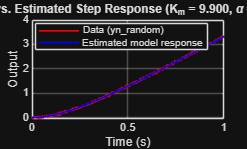

opt = stepDataOptions('StepAmplitude', 2);

sys_est = tf(T2_km_est, [1 T2_alpha_est 0]);
y_est   = step(sys_est, second, opt);
y_est   = y_est(1:length(yn_random));

figure;
plot(second(1:length(yn_random)), yn_random, 'r-', 'LineWidth', 1.2); hold on;
plot(second(1:length(yn_random)), y_est,     'b-', 'LineWidth', 1.2);
hold off;

xlabel('Time (s)');
ylabel('Output');
legend('Data (yn\_random)', 'Estimated model response', 'Location', 'best');
title(sprintf('Data vs. Estimated Step Response (K_m = %.3f, \\alpha = %.3f)', ...
    T2_km_est, T2_alpha_est));
grid on;

***ANSWER (edit below text section)***

#### Task 2.3: [Quantitative assessment] 

Comment on why/if your parameter estimates are quantitative accurate and whether the estimated step response is qualitatively similar (100-200 words, indicative length). Your answer should reference the parameter errors, and the qualitative visual match between step response data `yn_random` and your estimated step response. (100-200 words, indicative length).

***ANSWER (edit below code block)***

%edit here




***ANSWER (edit below text section)***

<Edit Here>

## Task 3 (Challenge your estimator):

In this task we challenge your estimator on servo motor data with unknown parameters.

#### **Task 3.1: [Generate unique data] **

Create a second set of randomly assigned data using the following

MATLAB command:

GenerateUnknownData('EGB345UnknownData.csv',yourstudentnumber)

**The MATLAB code used to generate data will be unique to your student number and will have different (hidden) model parameters of 𝑲𝒎 and 𝜶. The generated data will correspond to the same sized step input as previous tasks (that is, 2V).**

You are required to conduct data analysis and estimate the model parameters of $K_m$ and $\alpha$. This will test whether your estimation process in Task 2 generalises to other sets of data.

#### Task 3.2: [Estimate Parameters] 

Adjust as necessary and apply your estimation code from Task 2. Record your estimated parameter values. Plot both the step response data from EGB345UnknownData (plotted in red) and your estimated model data (plotted in blue) on the same plot to highlight how well they match. 

Please use T3_km_est and T3_alpha_est as your variable names for your estimated model parameter values.

***ANSWER (edit below code block)***

%edit here
%T3_km_est=1
%T3_alpha_est=1


***ANSWER (edit below text section)***

<Edit Here>

#### Task 3.3: [Qualitative and quantitative assessment]

In relation to your Task 3.2 parameter value estimates and plot, provide both:

- your assessment of the qualitative similarity of estimated step response, and

- your prediction of the quantitative accuracy of your parameter estimates (e.g. percentage error in each value).

Include justification for your assessment and prediction. (250-500 words, indicative length).

This question is asking you to provide both a **quantitative prediction **and a **qualitative assessment **informed by what you observed in Task 2 (where you knew parameter values). You don’t know the true situation here in Task 3, but you are asked to make reasonable inference of error in estimated parameters from your qualitative assessment of the estimated step response. This lack of parameter knowledge what occurs in a real-world setting.

Your quantitative prediction needs to be expressed as a quantity.

***ANSWER (edit below text section)***

<Edit Here>

## Task 4 (Harder challenge):

In practical 1 of EGB345 you were provided with the experimentally measured speed of the Series Elastic Actuator (SEA) output for 2V step input.

You are told the transfer function of the input voltage to the angle speed is given by:

                                                
$$\frac{\Omega_L(s)}{E_a(s)}=\frac{N_1}{s^3+D_3s^2+D_2s+D_1}$$


where some example system parameters are $N_1 \approx 4600$, $D_3 \approx 150$, $D_2\approx900$ and $D_1 \approx 40000$.  These are not the true values, as each student will have different values.

#### Task 4.1: [Generate unique data] 

Create a second set of randomly assigned data using the following

MATLAB command: 

GenerateSEASpeedData('EGB345SEASpeedData.csv',yourstudentnumber);

#### Task 4.2: [Compose Estimator] 

Write MATLAB code to estimate $N_1$, $D_3$, $D_2$  and $D_1$from the generated data. Record your estimated parameter values. Plot both the step response data from\ EGB345SEASpeedData (plotted in red) and your estimated model data (plotted in blue) on the same plot to highlight how well they match. 

Please use T4_N1_est, T4_D3_est, T4_D2_est and T4_D1_est as your variable names for your estimated model parameter values.

***ANSWER (edit below code block)***

%edit here
%T4_N1_est=1
%T4_D3_est=1
%T4_D2_est=1
%T4_D1_est=1

***ANSWER (edit below text section)***

<Edit Here>

#### Task 4.3: [Qualitative and quantitative assessment]

In relation to your Task 4.2 parameter value estimates and plot, provide both:

- your assessment of the qualitative similarity of estimated step response (including determining the poles of your estimated transfer function, checking with the final value theorem, and using any relevant dominant poles considerations), and

- your prediction of the quantitative accuracy of your parameter estimates (e.g. percentage error in each value).

Include justification for your assessment and prediction (250-500 words, indicative length).

This question is asking you to provide both a **quantitative prediction** and a **qualitative assessment **informed by what you observed in Task 2 (where you knew parameter values). You don’t know the true situation here in Task 4, but you are asked to make reasonable inference of error in estimated parameters from your qualitative assessment of the estimated step response.  This lack of parameter knowledge is what occurs in a real-world setting.

Your quantitative prediction needs to be expressed as a quantity.

***ANSWER (edit below text section)***

<Edit Here>

#### Task 4.4 [Reflections on Task difficult relative to earlier tasks] 

Provide reflections on the relative estimation difficulty of Task 4 compared to Task 3. These reflections should include both qualitative and quantitative aspects.

***ANSWER (edit below text section)***

<Edit Here>

# Do not change below: Check for "Ready to Submit". 

This script checks your code's variable names. Will confirm if ready to submit. Creates a design summary that is used to evaluate your activity.

EGB345_DataNameChecker_SysId